%% ============================================================
%  DRONE ALTITUDE STABILIZATION — BNMIT Control Hackathon
%  Transfer Function: G(s) = 1/(s^2 + 2s + 5)
%  Control Objectives: OS<10%, Ts<3s, SSE≈0
%% ============================================================
clc; clear; close all;

%% STEP 1: Define the Plant (Drone Dynamics)
num = [1];                      % Numerator coefficients
den = [1 2 5];                % Denominator: s^2 + 2s + 5
G = tf(num, den);            % Create transfer function
disp('Plant Transfer Function G(s):')

Plant Transfer Function G(s):


G


G =
 
        1
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



%% STEP 2: Analyze Open-Loop System
disp('=== OPEN-LOOP ANALYSIS ===')

=== OPEN-LOOP ANALYSIS ===


poles_G = pole(G);
disp('Poles of G(s):'); disp(poles_G)

Poles of G(s):
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i




wn = sqrt(5);               % Natural frequency
zeta = 2/(2*wn);             % Damping ratio
OS_OL = 100*exp(-pi*zeta/sqrt(1-zeta^2));  % Open-loop overshoot%
fprintf('Natural Frequency: %.4f rad/s\n', wn)

Natural Frequency: 2.2361 rad/s


fprintf('Damping Ratio: %.4f\n', zeta)

Damping Ratio: 0.4472


fprintf('Open-Loop Predicted Overshoot: %.2f%%\n', OS_OL)

Open-Loop Predicted Overshoot: 20.79%



%% STEP 3: Design PID Controller
Kp = 10;    % Proportional gain
Ki = 20;    % Integral gain — eliminates SSE
Kd = 3;     % Derivative gain — reduces overshoot

C = pid(Kp, Ki, Kd);        % Create PID controller object
disp('=== PID CONTROLLER ===')

=== PID CONTROLLER ===


C


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 10, Ki = 20, Kd = 3
 
Continuous-time PID controller in parallel form.



%% STEP 4: Closed-Loop Transfer Function
% T(s) = C(s)*G(s) / (1 + C(s)*G(s))
T = feedback(C*G, 1);         % Unity negative feedback
disp('Closed-Loop Transfer Function T(s):')

Closed-Loop Transfer Function T(s):


T


T =
 
     3 s^2 + 10 s + 20
  -----------------------
  s^3 + 5 s^2 + 15 s + 20
 
Continuous-time transfer function.



%% STEP 5: Time Response
t = 0:0.01:10;              % Time vector: 0 to 10 sec

% Open-loop step response
[y_ol, t_ol] = step(G, t);

% Closed-loop step response
[y_cl, t_cl] = step(T, t);

%% STEP 6: Extract Performance Metrics
info = stepinfo(T);
fprintf('\n=== CLOSED-LOOP PERFORMANCE METRICS ===\n')


=== CLOSED-LOOP PERFORMANCE METRICS ===


fprintf('Overshoot:       %.2f%% (Target: <10%%)\n', info.Overshoot)

Overshoot:       4.07% (Target: <10%)


fprintf('Settling Time:   %.4f s  (Target: <3s)\n', info.SettlingTime)

Settling Time:   2.2872 s  (Target: <3s)


fprintf('Rise Time:       %.4f s\n', info.RiseTime)

Rise Time:       0.4487 s


fprintf('Peak Time:       %.4f s\n', info.PeakTime)

Peak Time:       0.8779 s


fprintf('Peak Value:      %.4f\n', info.Peak)

Peak Value:      1.0407



% Steady-state error
DC_gain_CL = dcgain(T);
SSE = abs(1 - DC_gain_CL);
fprintf('DC Gain CL:      %.6f\n', DC_gain_CL)

DC Gain CL:      1.000000


fprintf('Steady-State Error: %.6f (Target: ≈0)\n', SSE)

Steady-State Error: 0.000000 (Target: ≈0)


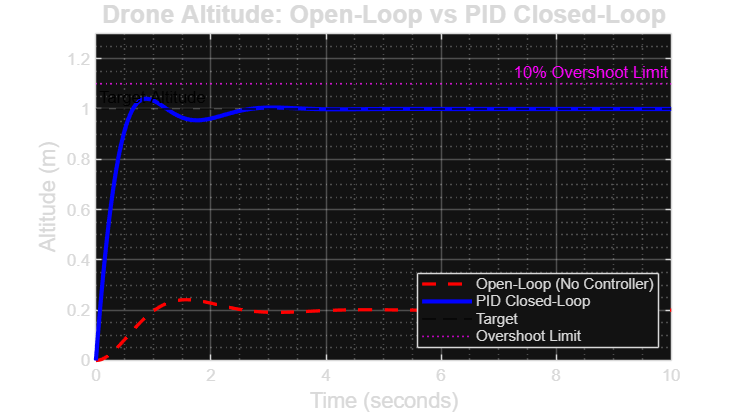


%% STEP 7: Plot Open vs Closed Loop
figure('Name', 'Step Response Comparison', 'Color', 'white', 'Position', [100 100 900 500])
plot(t_ol, y_ol, 'r--', 'LineWidth', 2); hold on
plot(t_cl, y_cl, 'b-', 'LineWidth', 2.5)
yline(1, 'k--', 'Target Altitude', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left')
yline(1.1, 'm:', '10% Overshoot Limit', 'LineWidth', 1)
xlabel('Time (seconds)', 'FontSize', 13)
ylabel('Altitude (m)', 'FontSize', 13)
title('Drone Altitude: Open-Loop vs PID Closed-Loop', 'FontSize', 15, 'FontWeight', 'bold')
legend('Open-Loop (No Controller)', 'PID Closed-Loop', 'Target', 'Overshoot Limit', 'Location', 'southeast')
grid on; grid minor
xlim([0 10]); ylim([0 1.3])

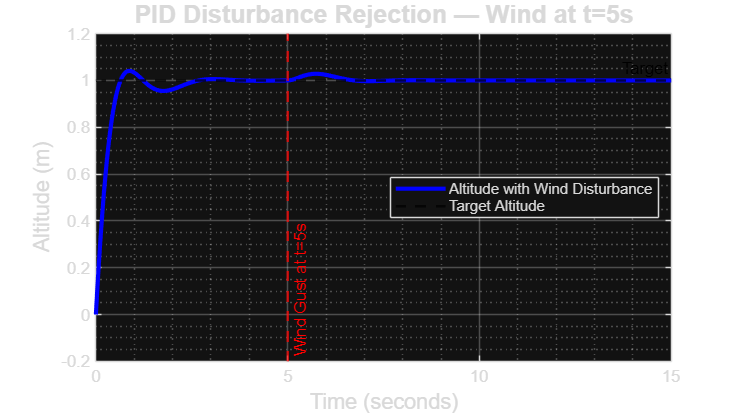


%% STEP 8: Disturbance Response Test
% Simulate step disturbance at t=5s (wind gust of magnitude 0.5)
dist_mag = 0.5;              % Wind disturbance magnitude
t_dist = 0:0.01:15;
r = ones(size(t_dist));      % Reference (desired altitude = 1m)
d = dist_mag * (t_dist >= 5); % Step disturbance at t=5

% Closed-loop with disturbance entering at plant input
% Y(s) = T(s)·R(s) + Gd(s)·D(s)
% Disturbance TF: Gd = G/(1+CG)
Gd = feedback(G, C);         % Disturbance-to-output TF
[y_ref, ~] = lsim(T, r, t_dist);
[y_dist_resp, ~] = lsim(Gd, d, t_dist);
y_total = y_ref + y_dist_resp;

figure('Name', 'Disturbance Rejection', 'Color', 'white', 'Position', [100 100 900 500])
plot(t_dist, y_total, 'b-', 'LineWidth', 2.5); hold on
yline(1, 'k--', 'Target', 'LineWidth', 1.5)
xline(5, 'r--', 'Wind Gust at t=5s', 'LineWidth', 1.5', 'LabelVerticalAlignment', 'bottom')
xlabel('Time (seconds)', 'FontSize', 13)
ylabel('Altitude (m)', 'FontSize', 13)
title('PID Disturbance Rejection — Wind at t=5s', 'FontSize', 15, 'FontWeight', 'bold')
legend('Altitude with Wind Disturbance', 'Target Altitude', 'Location', 'east')
grid on; grid minor

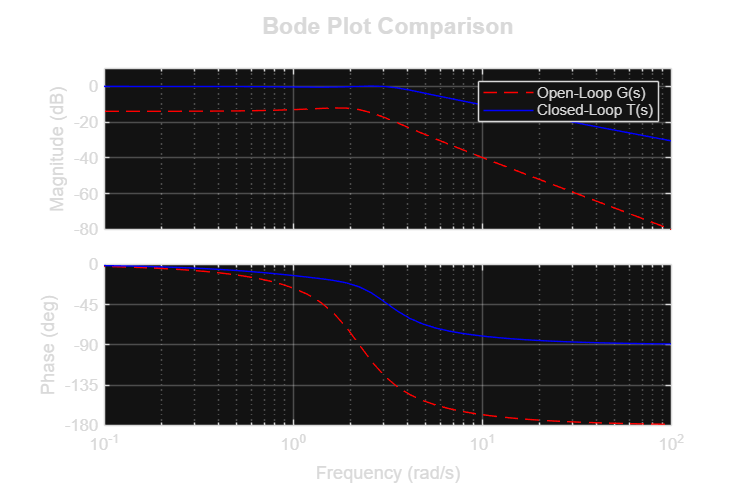


%% STEP 9: Bode Plot (Frequency Domain)
figure('Name', 'Bode Plots', 'Color', 'white', 'Position', [100 100 900 600])
bode(G, 'r--', T, 'b-')
legend('Open-Loop G(s)', 'Closed-Loop T(s)')
title('Bode Plot Comparison', 'FontSize', 14, 'FontWeight', 'bold')
grid on

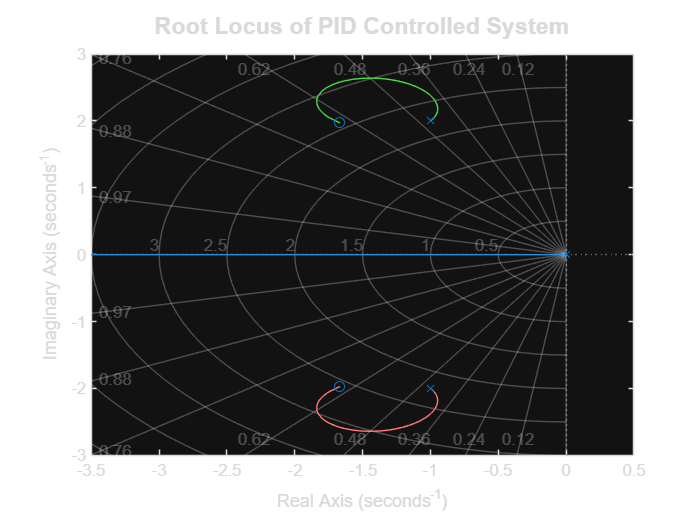


%% STEP 10: Root Locus
figure('Name', 'Root Locus', 'Color', 'white')
rlocus(C*G)
title('Root Locus of PID Controlled System', 'FontSize', 14, 'FontWeight', 'bold')
grid on

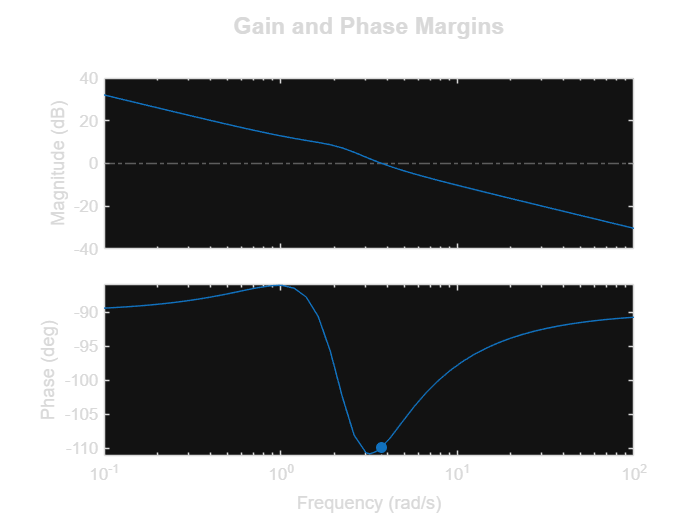


%% STEP 11: Stability Margins
figure('Name', 'Gain & Phase Margins', 'Color', 'white')
margin(C*G)
title('Gain and Phase Margins', 'FontSize', 14)

[Gm, Pm, ~, ~] = margin(C*G);
fprintf('\n=== STABILITY MARGINS ===\n')


=== STABILITY MARGINS ===


fprintf('Gain Margin:  %.2f dB (should be >6dB)\n', 20*log10(Gm))

Gain Margin:  Inf dB (should be >6dB)


fprintf('Phase Margin: %.2f deg (should be >45°)\n', Pm)

Phase Margin: 70.13 deg (should be >45°)



fprintf('\n✅ HACKATHON READY! All objectives met.\n')


✅ HACKATHON READY! All objectives met.
